# **DEMO:  **Test the Road profile model

In this example we'll test a **road profile model** that we'll use to stimulate our car dynamics(TRANSVERSE) models.  The road model involves defining a series of "humps" that are repeated along a stretch of road.  Specifically we'll:

- Introduce the parameterised road profile model

- Perform a simulation with a 1-dof transverse car dynamics model and investigate the acceleration g-forces experienced by the passengers of the car as it moves along the road.

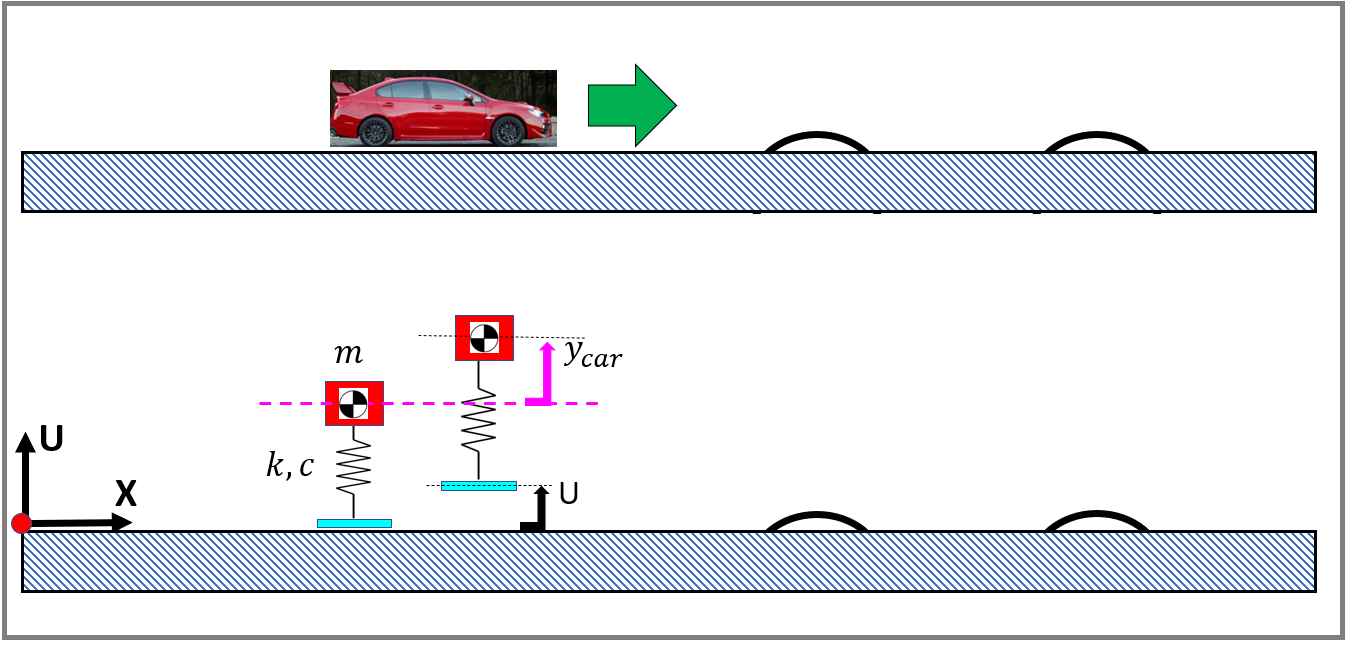

`Bradley Horton : 08-Aug-2021, bhorton@mathworks.com`

## The Road Profile model

Our Road profile model is summarised by the figure below.  Note the 4 parameters for this model:

- `   x_offset :`    (m)  the horizontal distance at which the FIRST hump begins

- `   Lx       :`    (m)  the **width** of the hump

- `   Hy       :`    (m)  the **Height** of the Hump

- `   P        :`    (m)  the spatial Period of the repeating block (ie: the distance between Humps)

The "Hump" portion is just a simple Sine wave of the form:

- 
$$U\left(x\right)\;={\;H}_Y \ldotp \sin \left(\frac{2\ldotp \pi \ldotp x}{\lambda }\right)\;=\;{\;H}_Y \ldotp \sin \left(\frac{2\ldotp \pi \ldotp x}{2\ldotp L_X }\right)\;=\;\;\;H_Y \ldotp \sin \left(\frac{\pi \ldotp x}{L_X }\right)$$


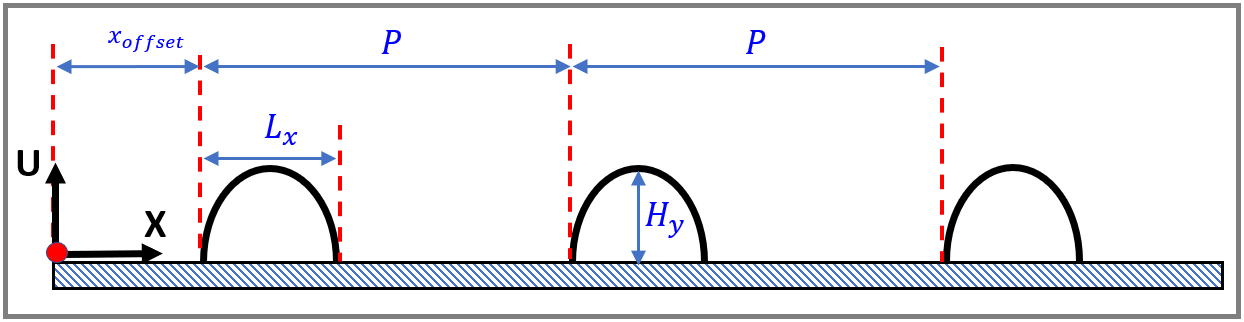

This road model is implemented in 2 files: 

- [`bh_road_profile_half_sine_periodic.mlx`](matlab:  edit bh_road_profile_half_sine_periodic.mlx) : this is a standard MATLAB function and defines the profile shown above

- [`bh_road_hump_A_SYSO.m`](matlab:  edit bh_road_hump_A_SYSO.m) : this is a System object class file.  We'll use this in our Simulink model. This simply uses the `bh_road_profile_half_sine_periodic.mlx `function .... AND it also allows us to "configure" a block for Simulink.  

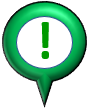**ATTENTION:**

- You do NOT have to use SYSTEM Objects in Simulink, but I have chosen to do so in this case. To demonstrate the options that you have, review the  Simulink model [`bh_road_in_simulink.slx`](matlab:  open bh_road_in_simulink.slx)  - it shows the Road Profile model implemented as a SYSTEM Object and also as a MATLAB Function block.  For NEW users of Simulink, [`the MATLAB Function block`](matlab:  web(fullfile(docroot, 'simulink/ug/what-is-a-matlab-function-block.html'))) is usually regarded as an **easier** approach.

- And lastly, a useful lookup table ([`bh_speed_vs_distance_explore.xlsx`](matlab:  winopen bh_speed_vs_distance_explore.xlsx)) relating car speed to corresponding distance travelled in 1 millisecond is listed below.

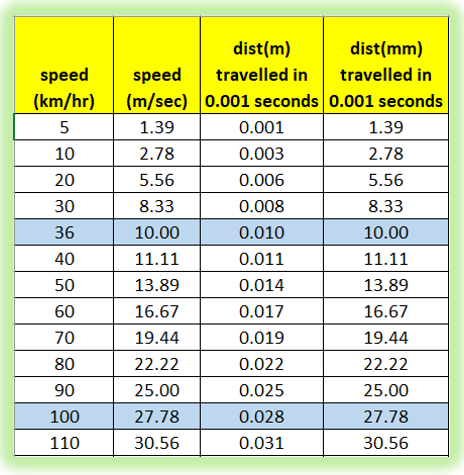

## Test the Road profile model

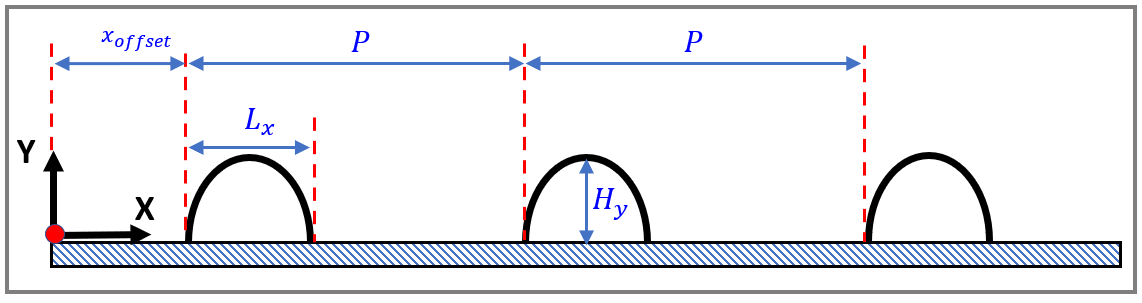

OK:  Let's explore a road profile

the_Hy          = 0.19;
the_Lx          = 0.8;
the_P           = 2.7;
the_x_offset    = 2;
the_NUM_PERIODS = 5;

OBJ = bh_road_hump_A_SYSO("Hy",the_Hy, "Lx",the_Lx, "P",the_P, ...
                          "x_offset",the_x_offset, "NUM_PERIODS",the_NUM_PERIODS);

Plot the road profile in the **spatial domain:**

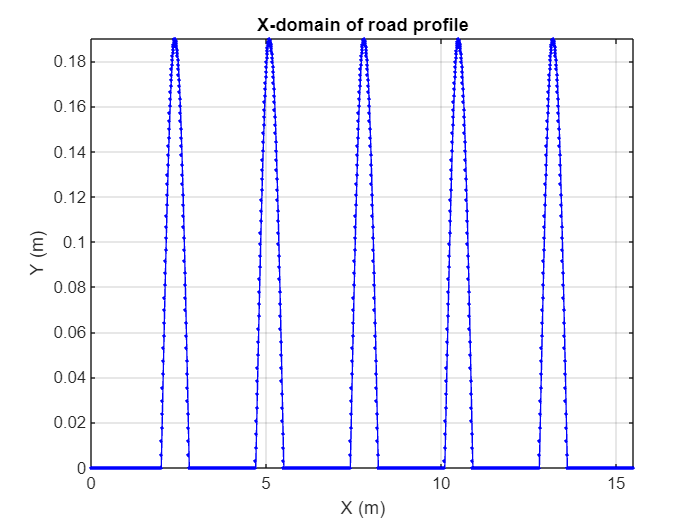

OBJ.plot_X_domain()

axis("tight")

For a constant car speed, plot the road profile in the **time domain:**

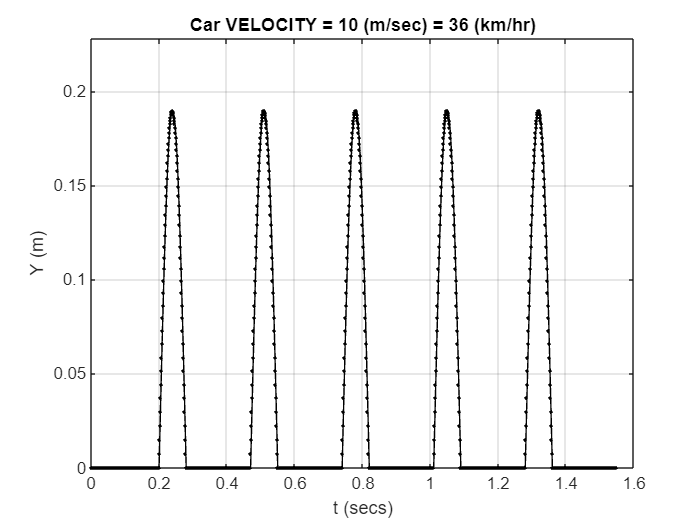

car_speed_mps = 10;  % (m/sec)

OBJ.plot_t_domain(car_speed_mps, "units", "m/s")

## Incorporate the road profile model into a Simulink model

Now let's test the road profile model by incorperating it into a Simulink file 

that also includes a 1-dof TRANSVERSE car dynamics model, ie:

- 
$$m\ldotp \ddot{y} \;=\;-k\left(y-U\right)\;-c\ldotp \left(\dot{y} \;-\;\dot{U} \right)$$


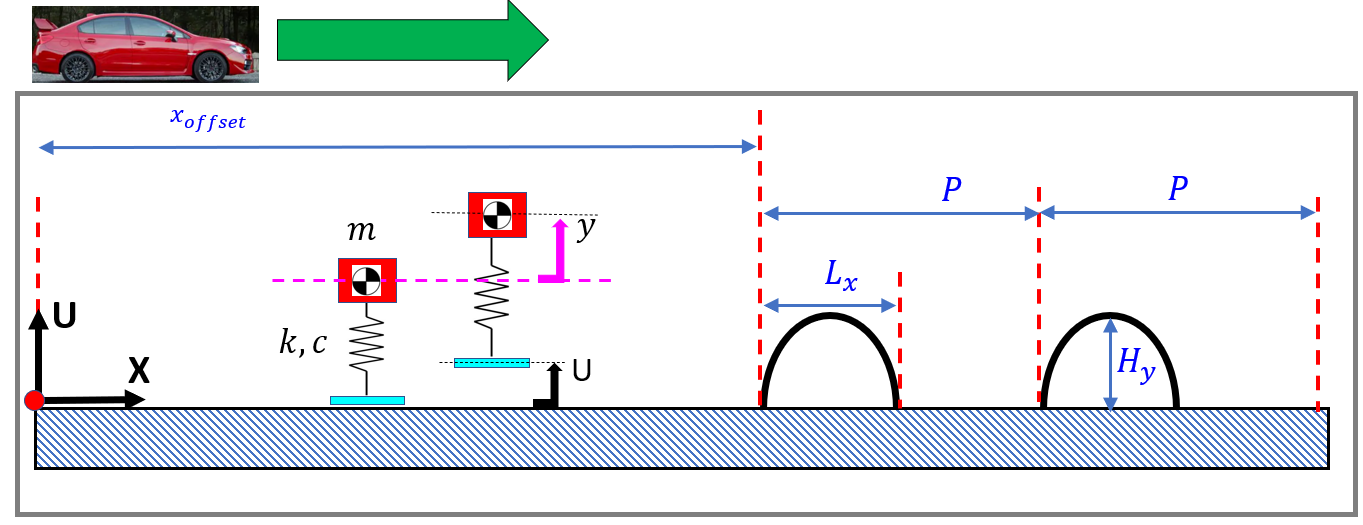

In the Simulink model, you can experiment with the road profile parameters and explore the impact that they have on the car dynamics:

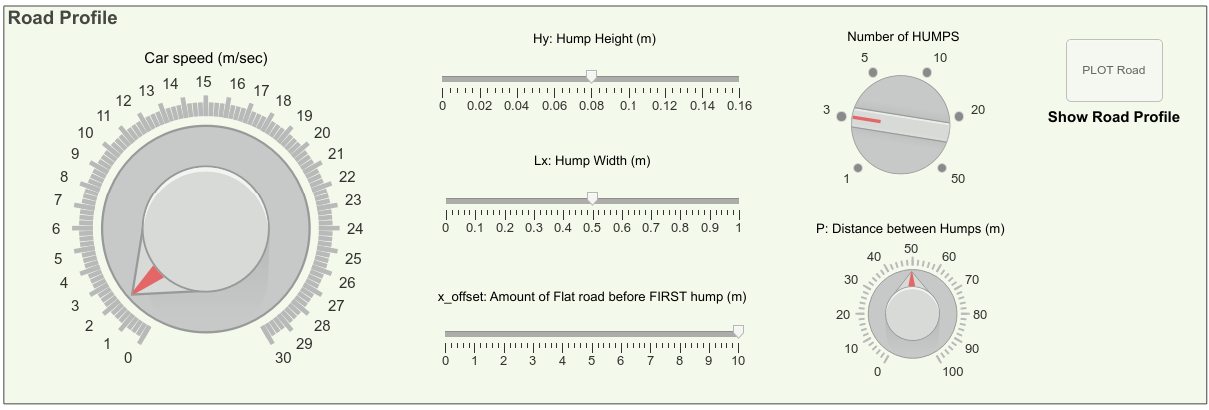

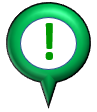** Investigate:**   the vertical displacement $y$ experienced by the car AND the vertical Acceleration $\ddot{y}$ experienced by the car(and passengers !) .  Try these experiments:

- `EXP_01:`    $v_{\textrm{CAR}} =\;\;1\;$(m/sec), $H_y =0\ldotp 12\;\left(m\right),L_X =0\ldotp 5\;\left(m\right),P=20\;\left(m\right)\;$

- `EXP_02:`    $v_{\textrm{CAR}} =10\;$(m/sec), $H_y =0\ldotp 12\;\left(m\right),L_X =0\ldotp 5\;\left(m\right),P=20\;\left(m\right)\;$

tf_open_model = true;
if(tf_open_model)
    open_system("bh_1dof_and_road_sim.slx")
end